**Dear Students, **

**Welcome to Lab 1 - Part 1 of your EE315 Course!**

**In this lab, we will explore and familiarise ourselves with the differences between continuous-time and discrete-time signals. **

#### **Note: **

- **In this notebook, you are expected to (i) write or/and complete code snippets (ii) write your observations and inferences based on the results of the code. You can write your answers inferences just after the question where ANSWER is mentioned. **

- **If you feel that some information is missing for carrying out your exercises, you can assume them appropriately. Please remember to state your assumptions.  If you find typos in the notebook, please let us know.  **

**You are expected to submit the solved notebook by 24th October 2020, 11.59pm. **

### **References: **

- **https://classroom.google.com/u/0/w/MTUyODczMTg4NDQ2/tc/MTM5MzAwNjc0NjY5**

# **Continuous-Time & Discrete-Time Sinusoids (60 Points)**

**Learning Outcome**: At the end of this exercise, you will be able to find out the differences between the continuous-time and discrete-time sinusoids. 

## Continuous-Time Sinusoids

Recall that the real continuous-time sinusoid is given by

                                                                           
$$x(t) = \cos(\Omega t+\phi), \;\; t\in \mathbb{R}$$
 

In the above equation, $t$ is the independent variable and $\Omega$ (radians/second) and $\phi$(radians) are the parameters, respectively, referred to as the frequency and phase of the continuous-time sinusoid. Note that $\Omega =2\pi \;F$, where $F$ is the frequency in $\textrm{Hz}\ldotp \;$

Now, you will construct and plot a continuous-time sinusoid. Remember that we are working on a digital computer. Hence, you need to devise a way to emulate the continuous-time in a digital computer. 

### **Coding (10 Points):                                                                   **

Question 1: Construct and plot a continuous-time sinusoid when $\Omega =\;\Omega_0 =\frac{\pi }{3}$ radians/second and ${\phi =\phi }_0 =0$ radians (plot $4$ cycles). 

#### **Initialization:                                                                                                                                  **

% Choose appropriate numerical values for the below variable to emulate continuous-time in the digital computer
step = [0.1];    % EXERCISE - Resolution of time variable
nCycles = [4]; % EXERCISE - Number of cycles required
Omega = [pi/3];  % EXERCISE - Radian frequency
phi = [0];    % EXERCISE - Phase

period = [2*pi/Omega];  % EXERCISE - Compute the period of the sinusoid
t = 0: step: [24]; % EXERCISE - Fill in the blank to plot 4 cycles of the sinusoid.
sinusoidCT =  zeros(1,[length(t)]); % EXERCISE - this is x(t). Initialize it to zero, for each value of "t"

#### **Construction: **

sinusoidCT =  [sin(Omega*t + phi)]; % EXERCISE - construct continuous-time sinusoid. 

#### **Plotting:**

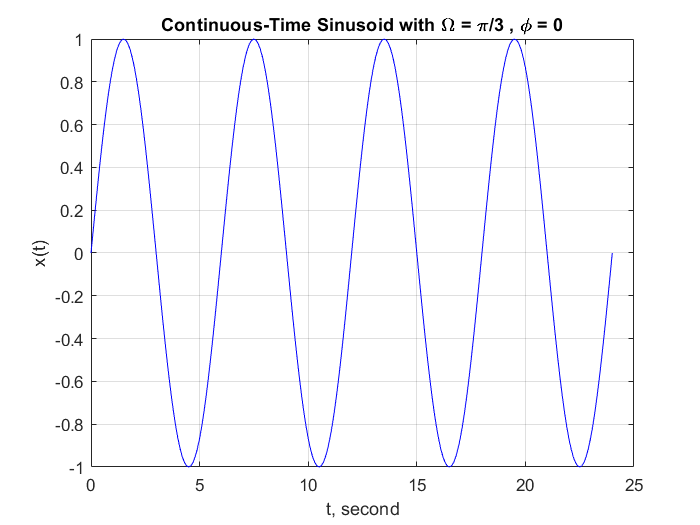

plot(t, sinusoidCT, 'b') 
title('Continuous-Time Sinusoid with \Omega = \pi/3 , \phi = 0')
xlabel('t, second')
ylabel('x(t)')
grid

### **Inferences (10 Points):   **

Now, play with the above constructed continuous-time sinusoid, make observations and write down your inference. 

- For any $\Omega$, the  continuous-time sinusoid is (SAY PERIODIC/APERIODIC)

             ANSWER:  Periodic  

- If you increase $\Omega$, the period  (*COMPLETE THE SENTENCE HERE*).

              ANSWER:  Decreases

- If you increase $\Omega$,  the rate of oscillations  (*COMPLETE THE SENTENCE HERE*).

              ANSWER:  Increases

- Can any two continuous sinusoids with two different frequencies be same? *(WRITE YOUR ANSWER HERE)*

              ANSWER:  No , two continuous sinusoids with different frequencies are distinct.

- What does the variable "step" represent in the above code?

              ANSWER: A continuous function is defined at infinitely many points, but  due to memory and computational limitations of a computer it is not possible to define a function at infinitely many points. Hence, instead of computing the value of the function at infinite points we calculate it after a certain small intervals of time. The **step** variable is the amount of that small interval. 

## **Practical Experiment  (10 Points)**

Now, construct and plot a continuous-time sinusoid when $\Omega =\;\Omega_0 =\frac{\pi }{3}$ radians/second and ${\phi =\phi }_0 =0$ radians. 

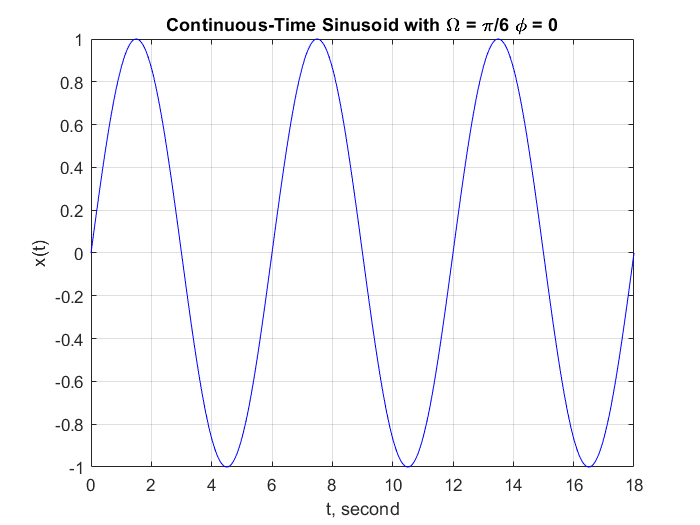

% Enter your code here

nCycles = 3;
step = 0.01; 
w = pi/3;  %Omega
phi = 0;  %phase
period = 2*pi/w;

t = 0 : step : nCycles*period;  % time
sinCT = sin(w*t + phi); % sin wave 

plot(t, sinCT, 'b') 
title('Continuous-Time Sinusoid with \Omega = \pi/6 \phi = 0')
xlabel('t, second')
ylabel('x(t)')
grid

Write code to listen to the above generated signal. Note that you will need to associate your variable "t" with the physical time to listen the true signal of frequency $\Omega$. (see [sound](https://in.mathworks.com/help/matlab/ref/sound.html))

% Find out a function from Matlab to play a vector.
sound(sinCT,1000);

- What sampling frequency did you use in the above code? Why? 

              ANSWER: 

- Change the sampling frequency while playing the sound and listen to the sound. What happens when you increases and decrease the sampling frequency? 

              ANSWER: As we increase the value of sampling frequency the sound of the beats become faster. And when we decrease the value of sampling frequency the speed of the beats decreases. 

## Discrete-Time Sinusoids

Now, let us sample the continuous-time sinusoid with the sampling frequency, $F_s \ge 2F$. Let us select, $F_s =\;\;2$ Hz implying that $T_s =0\ldotp 5$second. 

In this case, we are going to take samples of $x\left(t\right)$ at  $t=0T_{s\;} ,1T_s ,2T_s$and so on and we will get the following sequence: $\left\lbrace x\left\lbrack 0\right\rbrack \;=\;x\left(0T_s \right),\;x\left\lbrack 1\right\rbrack \;=\;x\left(1T_s \right),\;x\left\lbrack 2\right\rbrack \;=\;x\left(2T_s \right),\dots \right\rbrace \ldotp \;$

Compactly, this can be denoted as 

                                                                $x\left\lbrack n\right\rbrack =\;\cos \left(\Omega \;T_{s\;} n+\phi \right)\;=\;\cos \left(\omega \;n+\phi \right),\;\;\;\;n\in Z$, 

where  $\omega =\Omega \;T_s$ with radians/sample as the unit. We refer to $\omega$ as the discrete-time frequency, due to its similarity to the continuous-time frequency (strictly speaking, it is not a frequency, as x[n] may not even be periodic).  Note that $\omega =2\pi \;f$, where the unit of$f$ is $\frac{1}{\textrm{Samples}}$. 

### **Coding (10 Points):    **

Question 2: Construct and plot a discrete-time sinusoid when $\omega =\omega_0 =\Omega \;T_s$ radians/sample and ${\phi =\phi }_0 =0$ radians

#### **Initialization:                                                                                                                                  **

samplingPeriod =  [0.5]; %EXERCISE: Sampling period
nSamples = [4*period/samplingPeriod]; %EXERCISE: Number of samples in 4 cycles of the continuous-time wave, in the first case. 
n = 0: [1]: [nSamples]; % EXERCISE: Independent variable for the discrete-time sinusoid
omega = Omega * [samplingPeriod]; % EXERCISE: Discrete-time frequency from the continuous-time frequency
sinusoidDT = zeros(1,[length(n)]); % EXERCISE - this is x[n]. Intialize it to zero, for each value of "n"
disp(omega);

    0.5236



#### **Construction: **

sinusoidDT =  [sin(omega*n + phi)];  % EXERCISE - construct discrete-time sinusoid. 

#### **Plotting:**

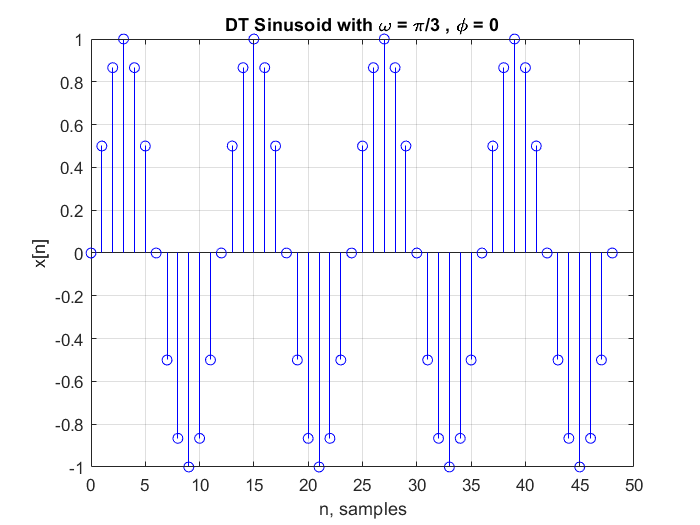

stem(n, sinusoidDT, 'b')
title('DT Sinusoid with \omega = \pi/3 , \phi = 0')
xlabel('n, samples')
ylabel('x[n]')
grid

### **Inferences (10 Points):   **

 Now, play with the above constructed discrete-time sinusoid, make observations and write down your inference. 

- Is the $x\left\lbrack n\right\rbrack$ constructed by you periodic? 

              ANSWER: Yes, it is periodic with period = 12.

- Let $x_1 \left\lbrack n\right\rbrack =\;\cos \left(\omega_{0\;} n+\phi \right)$ (This is the sequence you have constructed above). Now, construct another sequence $x_2 \left\lbrack n\right\rbrack =\;\cos \left(\left(w_0 +2\pi \right)n+\phi \right)$ (You can write a separate snippet of code or modify appropriate variables in the above code itself). Based on your simulations, compare $x_1 \left\lbrack n\right\rbrack$ and $x_2 \left\lbrack n\right\rbrack$. Can you generalize your conclusion?

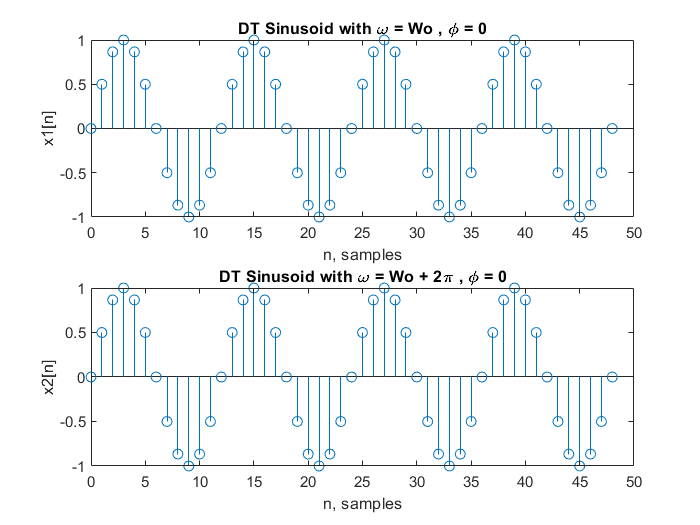

x1 = sinusoidDT;
x2 = sin((omega + 2*pi)*n + phi);

figure(1);
subplot(2,1,1);
stem(n,x1);
title('DT Sinusoid with \omega = Wo , \phi = 0')
xlabel('n, samples')
ylabel('x1[n]')
subplot(2,1,2);
stem(n,x2);
title('DT Sinusoid with \omega = Wo + 2\pi , \phi = 0')
xlabel('n, samples')
ylabel('x2[n]')

              ANSWER: As we can see in the plot for any $w_0$, the discrete sinusoid created with  $\omega$ = $w_0 +2\pi$ is the same as the one with $\omega$ = $w_0 +2\pi$.  also we can see this matematically, as we add 2$\pi$ to omega indirectly we can say that we are adding a phase of 2$\pi$n to the pase of our original sinusoid, and as we know that all the sinusoids are $2\pi$ periodic hence we can say that  **we will not get distinct discrete sinusoids for distinct values of **$\omega$**.**

- Now vary $\omega$, do you think that for every $\omega$, the sequence $x\left\lbrack n\right\rbrack$is periodic? If not, write down the condition on $\omega$ for $x\left\lbrack n\right\rbrack \;$to be periodic

            ANSWER: No, **for every value of **$\omega$** the sequence  **$x\left\lbrack n\right\rbrack$** is not periodic**. the condition on $\omega$ for the DT sinusoid to be periodic is: 

                                                                 $\omega \;=2\ldotp \pi \ldotp r$ here **r** can be any **rational number**. so that we can select some possible period  N such that $\omega$.N = 2m$\pi$ where m belongs to any integer. 

- Now vary $\omega$ $0\;\textrm{to}\;2\pi$. What happens to the rate of oscillation of $x\left\lbrack n\right\rbrack$when $\omega$ is varied from $0\;\textrm{to}\;\pi$ and $\pi \;\textrm{to}\;2\pi$?                        

              ANSWER:  Rate of Oscillations increases when $\omega$ is varied from $0\;\textrm{to}\;\pi$and decreases in $\pi \;\mathrm{to}\;2\pi$

### CONCLUSIONS (10 Points)

- Compare and contrast the differences between continuous-time and discrete-time sinusoids. 

              ANSWER: 1) CT sinusoids are always periodic whereas DT sinusoids may not always be periodic.

                                2) We get distinct sinusoids for distinct values of $\Omega$  in the case of CT sinusoids, whereas we don't get distinct sinusoids

                                    for distinct values of $\omega$ in case of DT.

- Do the above conclusions hold true for continuous-time and discrete-time complex sinusoids, with $x\left(t\right)=\textrm{Aexp}\;j\left(\;\Omega t+\phi \right)\;\;$ and $x\left\lbrack n\right\rbrack =A*\exp \;j\left(\textrm{wn}+\phi \right)$, where $A$ is the amplitude.   

              ANSWER: Yes, the above conclusions hold true for complex sinusoids. We can say this because after all, a complex sinusoid is nothing

                                but a linear combination of real sinusoids. 

# **Continuous-Time & Discrete-Time Sawtooth and Square Signals (40 Points)**

## Continuous-Time and Discrete-Time Square Signal

### **Coding (10 Points):                                                                   **

Question 1: Construct and plot a continuous-time square signal of a frequency and duty cycle of your choice. 

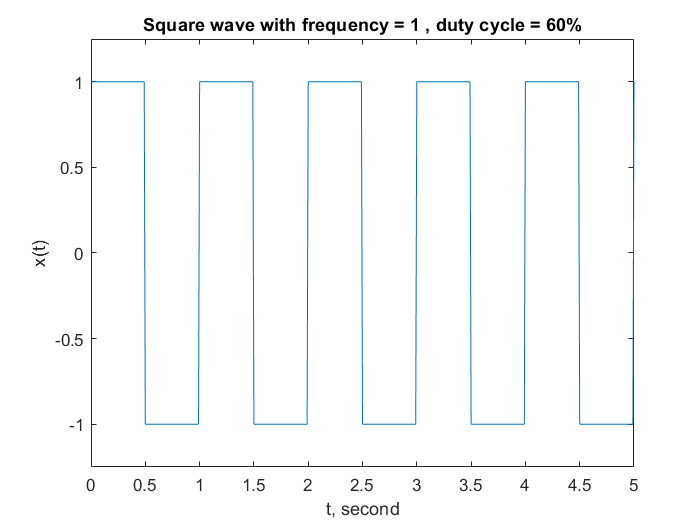

% WRITE YOUR CODE HERE
T = 5;
t = 0:0.01:T;
duty = 50;
freq = 1;
Omega = 2*pi*freq;

y = square(Omega*t , duty);
subplot(1,1,1);
plot(t,y);
title("Square wave with frequency = 1 , duty cycle = 60%");
xlabel('t, second')
ylabel('x(t)')
ylim([-1.25 1.25]);

Question 2: Now, sample the above signal with appropriate sampling frequency and plot the sequence.

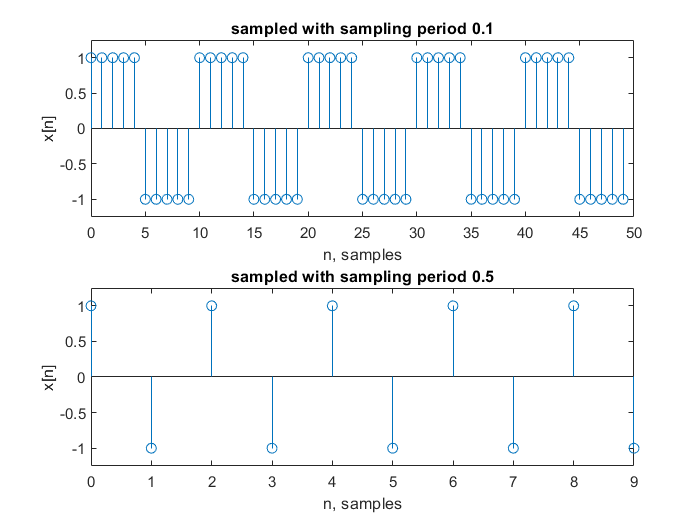

% WRITE YOUR CODE HERE

samplingPeriod1 = 0.1;
samplingPeriod2 = 0.5;

n1 = 0 : 1 : T/samplingPeriod1 - 1;
n2 = 0 : 1 : T/samplingPeriod2 - 1;

omega1 = Omega * samplingPeriod1;
omega2 = Omega * samplingPeriod2;

y1 = square(omega1*n1 , duty);
y2 = square(omega2*n2 , duty);

subplot(2,1,1);
stem(n1,y1);
title("sampled with sampling period 0.1");
xlabel('n, samples')
ylabel('x[n]')
ylim([-1.25 1.25]);
subplot(2,1,2);
stem(n2,y2);
title("sampled with sampling period 0.5");
xlabel('n, samples')
ylabel('x[n]')
ylim([-1.25 1.25]);

### Inference **(10 Points):     **

What are your observations?

  ANSWER: As we see from the plots, when we set the value of sampling period = 0.1 we are able to visualize a square wave with duty cycle of

                     50%, whereas when we set the value of sampling period = 0.5 we are not able to visualize a square wave.

                    Hence we can conclude that there is a certain maximum sampling period above which we cannot reconstruct a CT wave from the

                    sampled version.

## Continuous-Time and Discrete-Time Triangular Signal

### **Coding (10 Points):                                                                   **

Question 1: Construct and plot a continuous-time triangular signal of parameters of your choice. 

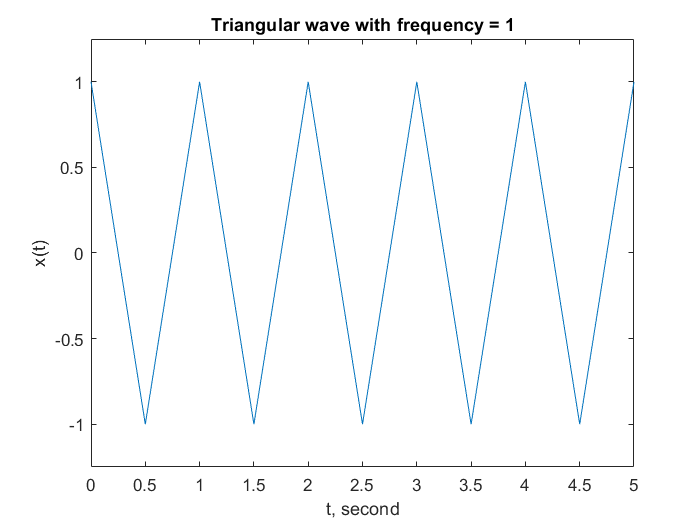

% WRITE YOUR CODE HERE
T = 5;
t = 0:0.01:T;
freq = 1;
Omega = 2*pi*freq;

y = -sawtooth(Omega*t,1/2);
subplot(1,1,1);
plot(t,y);
title("Triangular wave with frequency = 1");
xlabel('t, second')
ylabel('x(t)')
ylim([-1.25 1.25]);

Question 2: Now, sample the above signal with appropriate sampling frequency and plot the sequence.

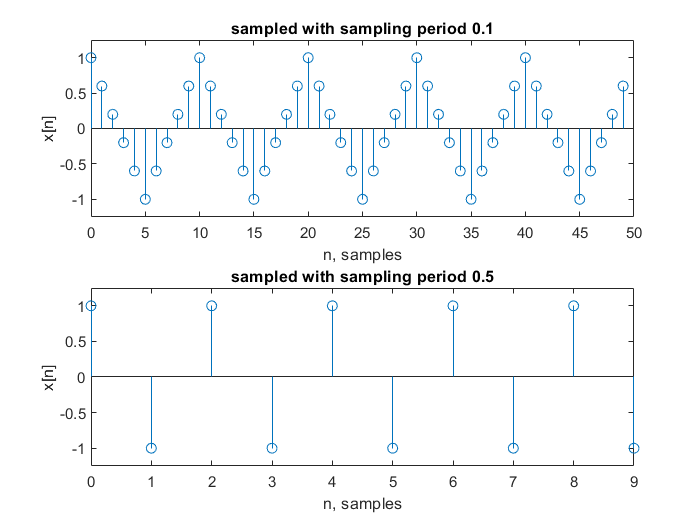

% WRITE YOUR CODE HERE
samplingPeriod1 = 0.1;
samplingPeriod2 = 0.5;

n1 = 0 : 1 : T/samplingPeriod1 - 1;
n2 = 0 : 1 : T/samplingPeriod2 - 1;

omega1 = Omega * samplingPeriod1;
omega2 = Omega * samplingPeriod2;

y1 = -sawtooth(omega1*n1 , 0.5);
y2 = -sawtooth(omega2*n2 , 0.5);

subplot(2,1,1);
stem(n1,y1);
title("sampled with sampling period 0.1");
xlabel('n, samples')
ylabel('x[n]')
ylim([-1.25 1.25]);
subplot(2,1,2);
stem(n2,y2);
title("sampled with sampling period 0.5");
xlabel('n, samples')
ylabel('x[n]')
ylim([-1.25 1.25]);

### Inference **(10 Points):     **

What are your observations?

  ANSWER: By seeing the plots we can come to similar conclusions as in the square waveform case. We are able to visualize a triangular wave

                    when sampling period = 0.1, whereas we are unable to do so when we take ampling period = 0.5.

                    Mixed inference(for the last 2 parts):

                    It's not very clear when we say that we cannot reconstruct our waveform from the sampled versionjust by visualization.

                    So to make it clear we can take a look at the plots for sampling period = 0.5 in both the above cases.(triangular and square waves)

                    If we observe them carefully they are exactly the same, the only difference between them is that they are sampled from different 

                    waveforms.Hence, we can conclude that we cannot reconstruct the waveform in the above examples if we set sampling period = 0.5

                    Finally we can give a general conclusion from the two parts above using Nyquist sampling theorem,

                    We can reconstruct our wave form from the sampled version if,

                                                            $\frac{1}{\mathrm{Ts}}\;>=\;2\ldotp F\;$ here F is the maximum frequency component of a given CT signal.